# Batch-processing vs Recursive

## Batch processing

Batch-processing method needs that all of the measurements had to be taken before any estimates of the best polynomial coefficients could be made.

### Zero-Order or one State Filter

Zero for no **'t'** in the polinomy

One state for $a_0$

#### Data and equations

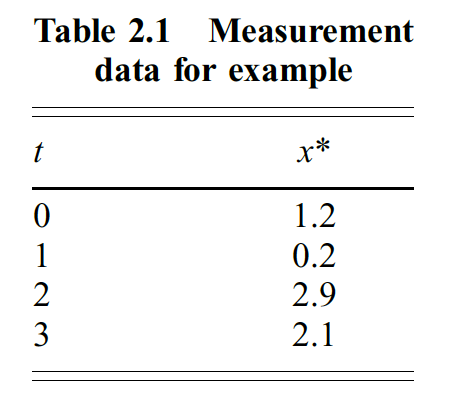

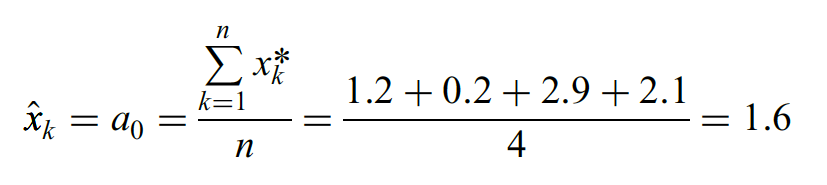

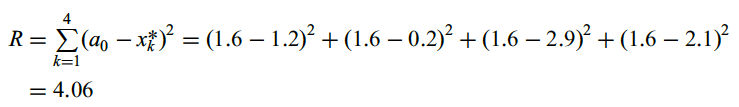

k=(1:1:4)'

k =      1
     2
     3
     4


x_m=[1.2 0.2 2.9 2.1]

x_m =     1.2000    0.2000    2.9000    2.1000


x_h=mean(x_m)

x_h = 1.6000

#### Some easy statistics 

Standar deviation and Variance ($\[\sigma {\text{ and }}V = {\sigma ^2}\]$)

std_f=std(x_m)

std_f = 1.1633

Vstd=std_f^2

Vstd = 1.3533

V=var(x_m)

V = 1.3533

From Residuals

Be carefully with N sample

V=4.06/3

V = 1.3533

V=4.06/4

V = 1.0150

Also 

V=mean(x_m.^2)-mean(x_m)^2

V = 1.0150

#### Plotting for analysis

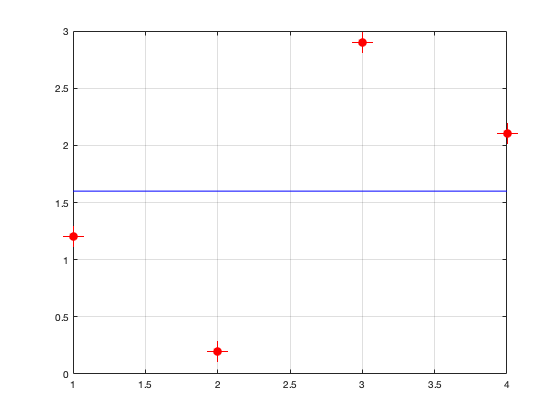

clf
plot(k,x_m,'r+','MarkerSize',20)
hold on
grid on
plot(k,x_m,'r.','MarkerSize',30)
plot(k,ones(length(k),1)*x_h,'b')

### First-Order or Two-State Filter

**First** for **'t'** in the polinomy

**Two** for $a_0 {\text{ and } }a_1$ in the polinomy

#### Data and equations

Suppose we would like to fit the measurement data with the best straight line (i.e., rather than a constant) in the least squares sense. This means we are seeking estimates to fit the first-order polynomial


$$\hat x=a_0+a_1t\\ {\hat \dot x}=a_1$$


or in discrete form


$$\hat x_k=a_0+a_1(k-1)T_s\\  {\hat \dot x_k}=a_1$$


where k is the number of measurements taken and Ts is the sampling time.

Using built-in Matlab** ' \ ' **function for solving least-squared equations

Remember we can transform $\hat x_k=a_0+a_1(k-1)T_s$ to matrix form


$$\[\left[ {\begin{array}{*{20}{c}}
  k&1 
\end{array}} \right] \left[ {\begin{array}{*{20}{c}}
  a_1 \\ 
  a_0 
\end{array}} \right] = x^*\]$$


for the first seven


$$\[\left[ {\begin{array}{*{20}{c}}
  1&1 \\ 
  2&1 \\ 
  3&1 \\ 
  4&1 \\ 
  5&1 \\ 
  6&1 \\ 
  7&1 
\end{array}} \right]\left[ {\begin{array}{*{20}{c}}
  {{a_1}} \\ 
  {{a_0}} 
\end{array}} \right] = \left[ {\begin{array}{*{20}{c}}
  {{\text{0.60}}} \\ 
  {{\text{0.80}}} \\ 
  {{\text{1.25}}} \\ 
  {2.14} \\ 
  {2.50} \\ 
  {3.15} \\ 
  {2.70} 
\end{array}} \right] \to Aa=m \to a=inv(A)m \to a = A\backslash m$$



close all
clear
clf
k=(1:1:7)'

k =      1
     2
     3
     4
     5
     6
     7


Ts=0.01

Ts = 0.0100

x_m=[0.6 0.8 1.25 2.14 2.50 3.15 2.7]' % Measurements

x_m =     0.6000
    0.8000
    1.2500
    2.1400
    2.5000
    3.1500
    2.7000


To see the measurements

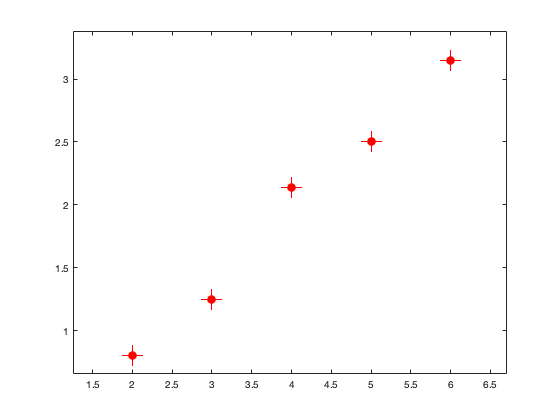

plot(k,x_m,'r+','MarkerSize',20) % measurements
hold on
plot(k,x_m,'r.','MarkerSize',30)

Forming the A matrix

A=[k ones(length(k),1)]

A =      1     1
     2     1
     3     1
     4     1
     5     1
     6     1
     7     1


Solving

a=A\x_m

a =     0.4375
    0.1271


a_1_hat=a(1)

a_1_hat = 0.4375

a_0_hat=a(2)

a_0_hat = 0.1271

x_k_h=a_0_hat+a_1_hat*k

x_k_h =     0.5646
    1.0021
    1.4396
    1.8771
    2.3146
    2.7521
    3.1896


#### Some easy statistics 

The residual 

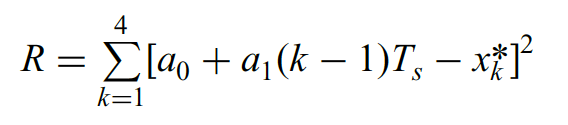

R_v=cumsum([x_k_h - x_m].^2,1)

R_v =     0.0013
    0.0421
    0.0781
    0.1472
    0.1815
    0.3398
    0.5796


R=R_v(end)

R = 0.5796

Variance

V=R/length(x_m)

V = 0.0828

#### Plotting for analysis

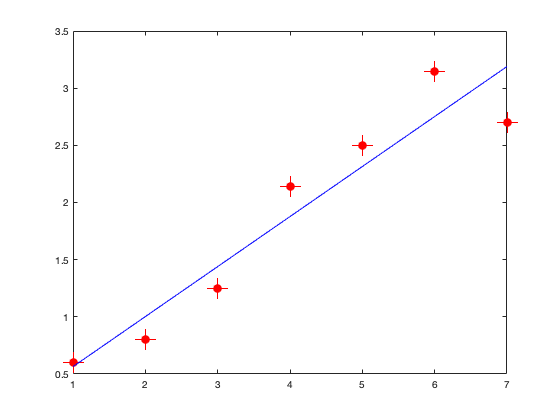

plot(k,x_m,'r+','MarkerSize',20) % measurements
hold on
plot(k,x_m,'r.','MarkerSize',30)
hold on;
plot(k,x_k_h,'b') % estimated

## Recursive

We use as a reference the book: 

Fundamentals of Kalman Filtering: A Practical Approach, by Paul Zarchan and Howard Musoff. Third Edtion.

Let us start with a simple example

### Zero-Order or one State Filter

Estimating a constant. 

The new estimate $\hat x_k$ simply depends on the old estimate plus a gain (i.e., $\frac {1}{k}$ for the zeroth-order filter) times a residual (i.e., $\[{x^*}\]$ current measurement minus preceding estimate)

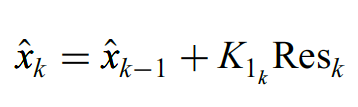


$$K_{1_k}=\frac{1}{k}$$


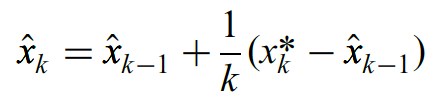

Covariance:


$$\[\sqrt {{P_k}}  = \frac{{{\sigma _n}}}{{\sqrt k }} \to {P_k} = \frac{{\sigma _n^2}}{k}\]$$


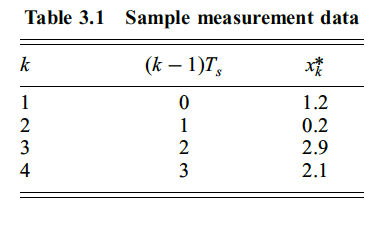

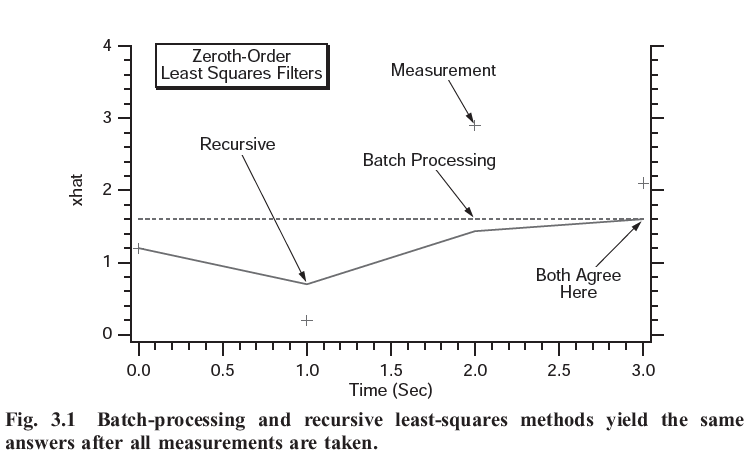

Notice we do not use ***'for'*** loop 

A0=1.6

A0 = 1.6000

k=(1:1:4)'

k =      1
     2
     3
     4


x_m=[1.2 0.2 2.9 2.1]

x_m =     1.2000    0.2000    2.9000    2.1000


x_h_ini=0 %is a initial guest

x_h_ini = 0

x_h(1)=x_h_ini+(1/k(1))*(x_m(1) - x_h_ini)

x_h = 1.2000

x_h(2)=x_h(1)+(1/k(2))*(x_m(2) - x_h(1))

x_h =     1.2000    0.7000


x_h(3)=x_h(2)+(1/k(3))*(x_m(3) - x_h(2))

x_h =     1.2000    0.7000    1.4333


x_h(4)=x_h(3)+(1/k(4))*(x_m(4) - x_h(3))

x_h =     1.2000    0.7000    1.4333    1.6000


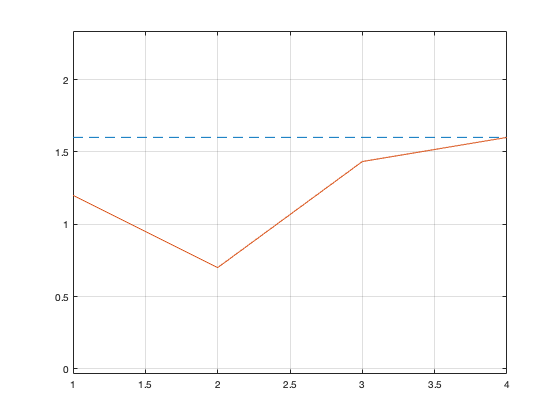

figure
plot(k,ones(1,4)*mean(x_m),'LineStyle',"--")
hold on
plot(k,x_h)
axis equal
grid on

sigma_m=1 % we can establish after observing the data

sigma_m = 1

P_k(1)=sigma_m/sqrt(k(1))

P_k = 1

P_k(2)=sigma_m/sqrt(k(2))

P_k =     1.0000    0.7071


P_k(3)=sigma_m/sqrt(k(3))

P_k =     1.0000    0.7071    0.5774


P_k(4)=sigma_m/sqrt(k(4))

P_k =     1.0000    0.7071    0.5774    0.5000


Error(1)= (A0-x_h(1))

Error = 0.4000

Error(2)= (A0-x_h(2))

Error =     0.4000    0.9000


Error(3)= (A0-x_h(3))

Error =     0.4000    0.9000    0.1667


Error(4)= (A0-x_h(4))

Error =     0.4000    0.9000    0.1667         0


Plotting: Measurement, Estimate & Signal

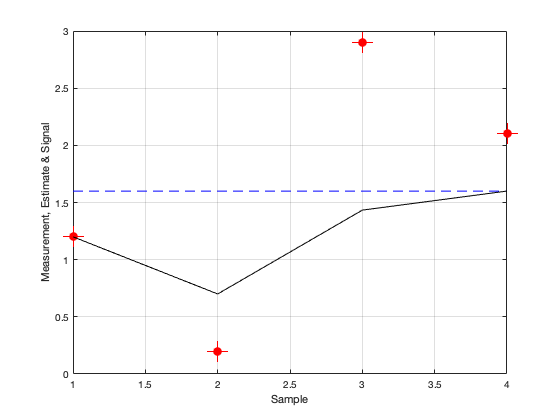

figure
plot(k,ones(1,4)*A0,'Color','b','LineStyle',"--") % signal
hold on
plot(k,x_m,'r+','MarkerSize',20)
hold on
plot(k,x_m,'r.','MarkerSize',30)
plot(k,x_h,'black')
grid on
xlabel('Sample')
ylabel('Measurement, Estimate & Signal')

Plotting: Error in Estimate

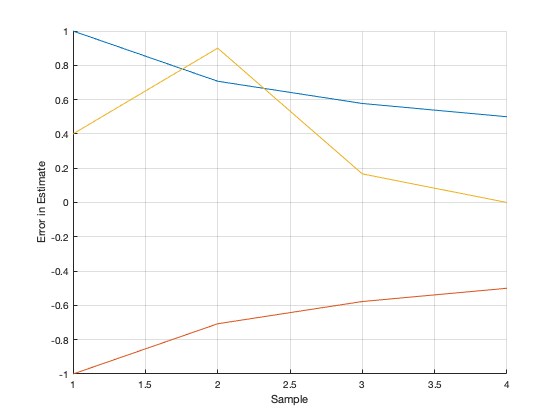

figure
hold on
plot(k,P_k,k,-P_k)
hold on
plot(k,Error)
grid on
xlabel('Sample')
ylabel('Error in Estimate')

### First-Order or Two-State Filter

#### Key ideas

Follows the train example


$$\hat x_k=a_0+a_1(k-1)T_s$$


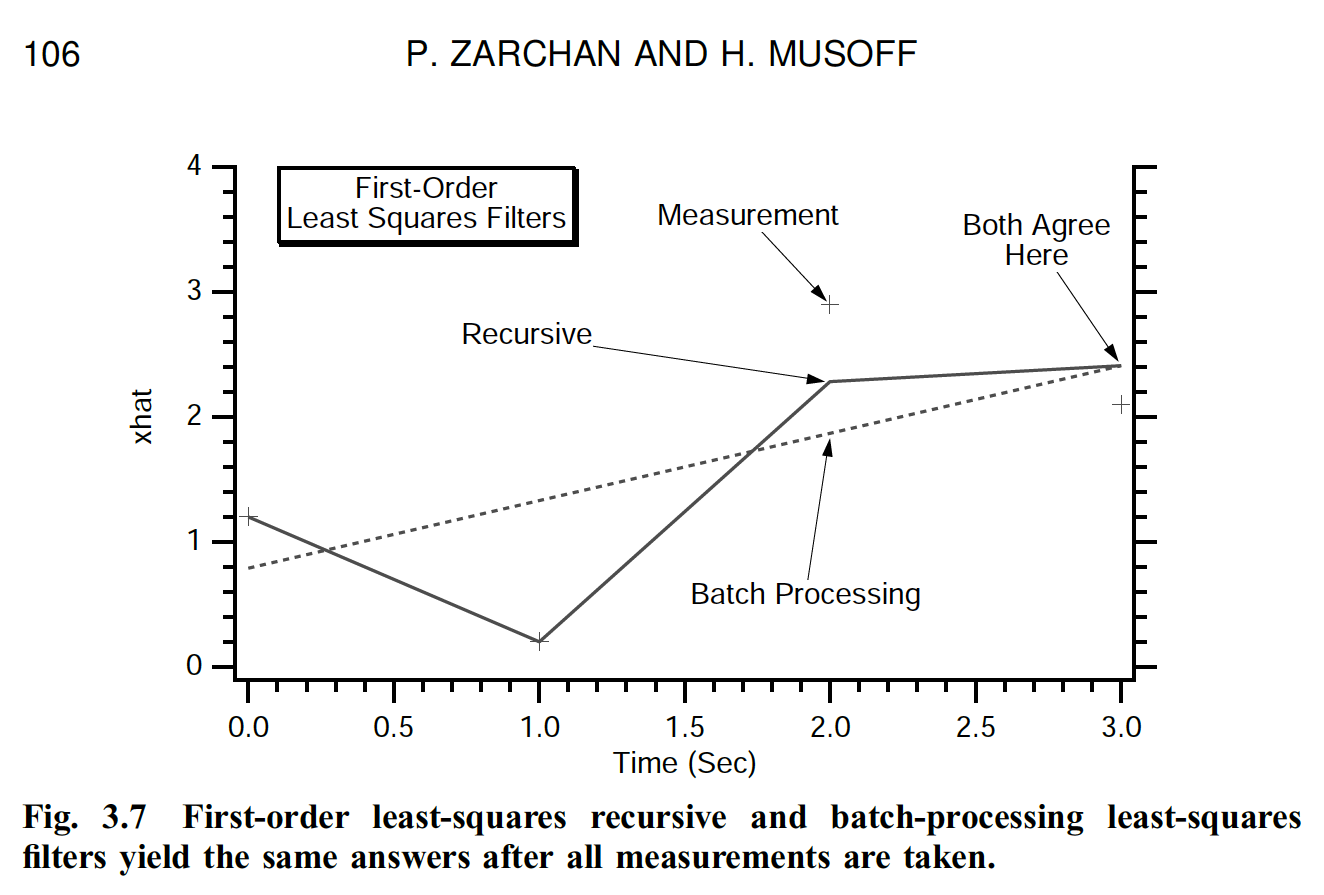

The Gain's

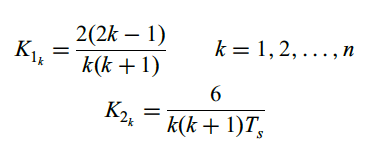

Residual

Estimated

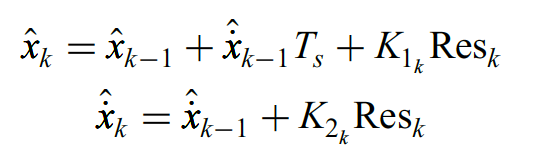

Covariancce

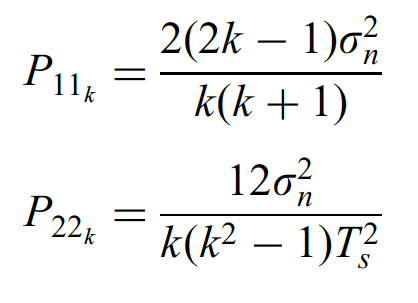

Errors